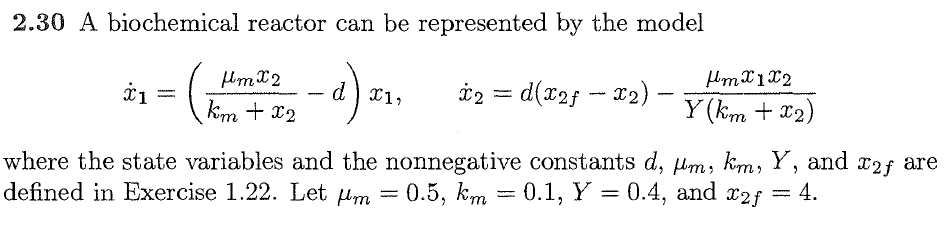

close all; clc

mu = 0.5;
k = 0.1;
capY = 0.4;
x2f = 4;

syms x1 x2 real
syms d positive
f1 = (mu*x2/(k+x2)-d)*x1;
f2 = d*(x2f-x2)-mu*x1*x2/(capY*(k+x2));

sln = solve([f1 f2], [x1 x2])
sln.x1
sln.x2

J = jacobian([f1 f2], [x1 x2]);
for i=1:numel(sln.x1)
    A = subs(J, [x1 x2], [sln.x1(i) sln.x2(i)]);
    eig(A)
end

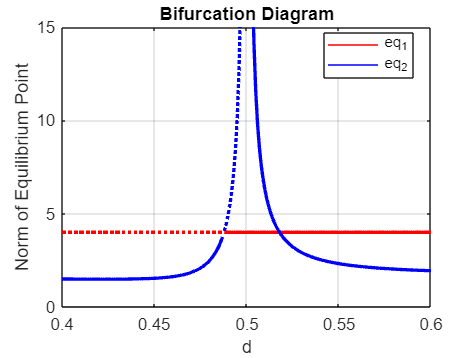

% equilibrium points as function of d
d = 0.40:0.001:0.60;
e1 = vecnorm([0*d+0; 0*d+4]);
e2 = vecnorm([(82*d-40)./(50*d-25); d./(5-10*d)]);
e1_lambda = [20/41-d; -d];
e2_lambda = [-d; -82*d.^2 + 81*d - 20];

unstable = (d < 20/41);
stable = (d >= 20/41);
plot(d(stable), e1(stable),'r-','LineWidth',2); hold on;
plot(d(unstable), e1(unstable),'r:','LineWidth',2);

unstable = (d >= 20/41) & (d <= 0.5);
stable1 = (d < 20/41);
stable2 = (d > 0.5);
plot(d(stable1), e2(stable1),'b-','LineWidth',2);
plot(d(stable2), e2(stable2),'b-','LineWidth',2);
plot(d(unstable), e2(unstable),'b:','LineWidth',2);

yline(0,'k-');
title('Bifurcation Diagram')
xlabel('d')
ylabel('Norm of Equilibrium Point')
grid on;
ylim([0 15])

qw{1} = plot(nan, 'r-');
qw{2} = plot(nan, 'b-');
legend([qw{:}],{'eq_1', 'eq_2'}, 'Location','best')
hold off;

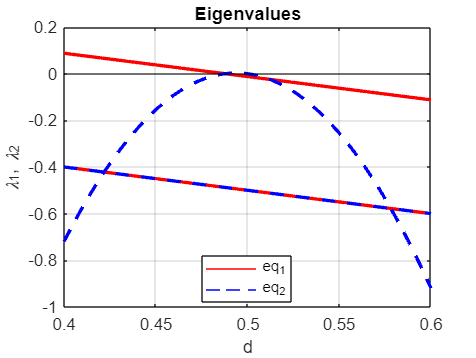

% eigenvalues as function of d
plot(d, e1_lambda,'r-','LineWidth',2); hold on;
plot(d, e2_lambda,'b--','LineWidth',2);
yline(0,'k-');

title('Eigenvalues')
xlabel('d')
ylabel('\lambda_1, \lambda_2')
xlim([d(1) d(end)])

% custom legend
qw{1} = plot(nan, 'r-');
qw{2} = plot(nan, 'b--');
legend([qw{:}],{'eq_1', 'eq_2'}, 'Location','best')
grid on
hold off

% Create vector field
close all;
x = linspace(0,4.1,30);
y = linspace(0,4.1,30);
[X,Y] = meshgrid(x,y);

d = 0.4;
DX = (mu*Y./(k+Y)-d).*X;                 
DY = d*(x2f-Y)-mu*X.*Y./(capY*(k+Y));

quiver(X,Y,DX,DY,1);
xlabel('x_1')
ylabel('x_2')
axis equal;
title("Vector Field")

hold on; 
f= @(t,P) [(mu*P(2)./(k+P(2))-d).*P(1); ...
    d*(x2f-P(2))-mu*P(1).*P(2)./(capY*(k+P(2)))];
x1_0 = [0 0.2 1 2 3];
x2_0 = [0 0.2 1 2 3 4];
for i = 1:numel(x1_0)
    for j=1:numel(x2_0)
        [t,s] = ode45(f,[0 60], [x1_0(i) x2_0(j)]);
        plot(s(:,1),s(:,2),'LineWidth',2)
        plot(x1_0(i), x2_0(j), 'bo')
    end
end

for i = 1:numel(sln.x1)
    s1 = subs(sln.x1(i), sym('d'), d);
    s2 = subs(sln.x2(i), sym('d'), d);
    plot(s1, s2, 'rx','MarkerSize',15,'LineWidth',3)
end
hold off